clear
clc
load("Y8.mat")
dt = 0.2; % Шаг времени
Jx = 2807;
Jy = 3374;
Jz = 3671;

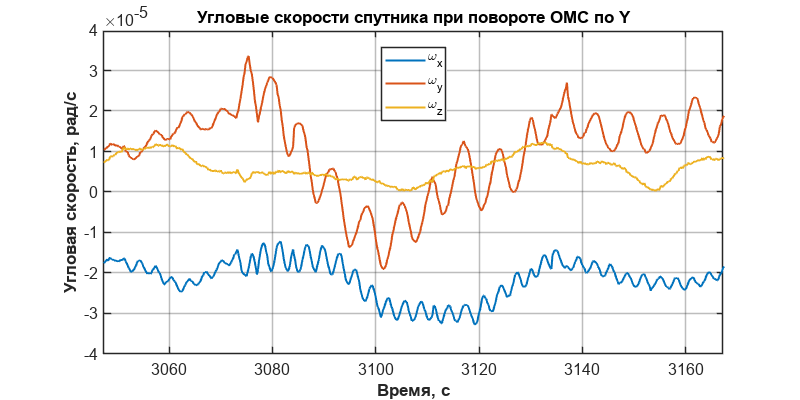

start = 15338-100;
len = 600;
data = Y8(start:start+len, :);

%Скорость
figure('Color','w', 'Position', [100, 100, 800, 400]);  % белый фон, ширина и высота

% Графики
plot(data.time, data.X2, 'LineWidth', 1.5); hold on;
plot(data.time, data.Y2, 'LineWidth', 1.5);
plot(data.time, data.Z2, 'LineWidth', 1.5);
ax = gca;               % текущая ось

% Сетка и подписи
grid on;
xlabel('Время, с', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Угловая скорость, рад/с', 'FontSize', 12, 'FontWeight', 'bold');
title('Угловые скорости спутника при повороте ОМС по Y', 'FontSize', 14);

% Легенда
legend({'\omega_x', '\omega_y', '\omega_z'}, 'Location', 'best', 'FontSize', 11);

% Оси и стиль
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3);  % прозрачность сетки

% Экспорт (по желанию)
 xlim([data.time(1) data.time(end)])
 saveas(gcf, 'angular_ratesY8.png');        % PNG
 exportgraphics(gcf, 'angular_ratesY8.pdf'); % PDF (векторный формат)

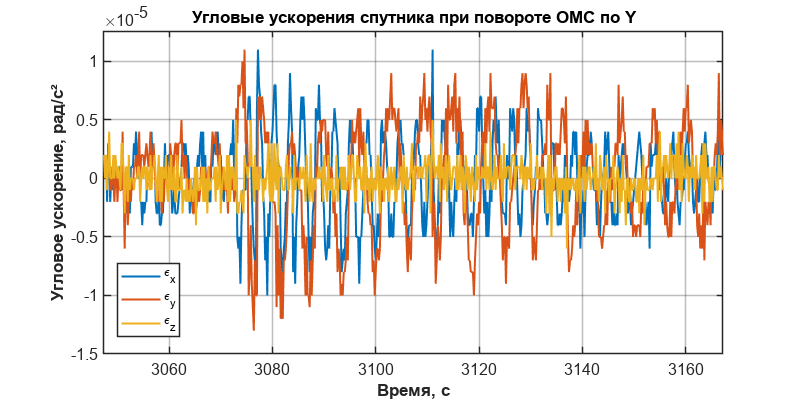

dx = diff(data.X2)/dt; 
[dx_max,ind] = max(dx);
dx(ind) =dx(ind+2); 
dy = diff(data.Y2)/dt;
[dy_max,ind] = max(dy);
dy(ind) =dy(ind+2);
[dy_min, indmin] = min(dy);
dy(indmin) = dy(ind+2);
dz = diff(data.Z2)/dt;
dift = data.time(1:end-1);
%% Ускорение
figure('Color','w', 'Position', [100, 100, 800, 400]);  % белый фон, ширина и высота

% Графики с толщиной линии
plot(dift, dx, 'LineWidth', 1.5); hold on;
plot(dift, dy, 'LineWidth', 1.5);
plot(dift, dz, 'LineWidth', 1.5);

% Сетка
grid on;

% Подписи осей
xlabel('Время, с', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Угловое ускорение, рад/c²', 'FontSize', 12, 'FontWeight', 'bold');

% Название графика (если нужно)
title('Угловые ускорения спутника при повороте ОМС по Y', 'FontSize', 14);

% Легенда
legend({'\epsilon_x','\epsilon_y','\epsilon_z'}, 'Location', ...
    'best', 'FontSize', 11);

% Настройки внешнего вида осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3);  % прозрачность сетки
% Ограничение по X
 xlim([data.time(1) data.time(end)])
% Дополнительно: плотные метки по Y, если у тебя малый диапазон
ylim padded  % добавить отступ сверху/снизу
 saveas(gcf, 'epsilon_ratesY8.png');        % PNG

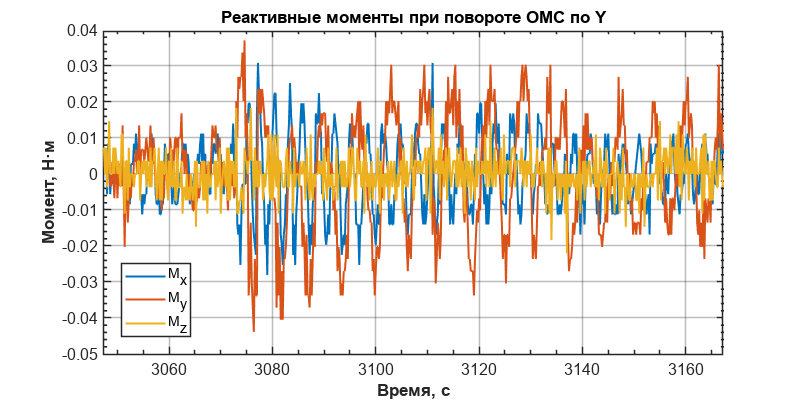

Mz = dz*Jz;
Mx = dx*Jx;
My = dy*Jy;
M_all = [Mx,My,Mz];
figure
figure('Color','w', 'Position',[100 100 800 400]);  % Белый фон, подходящий размер

% Предполагаем, что M_all — матрица Nx3: [Mx My Mz]
plot(dift, M_all(:,1), 'LineWidth', 1.5); hold on;
plot(dift, M_all(:,2), 'LineWidth', 1.5);
plot(dift, M_all(:,3), 'LineWidth', 1.5);

xlim([data.time(1) data.time(end) ]);
grid on;

% Подписи
xlabel('Время, с', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Момент, Н·м', 'FontSize', 12, 'FontWeight', 'bold');
title('Реактивные моменты при повороте ОМС по Y', 'FontSize', 14);

% Легенда
legend({'M_x', 'M_y', 'M_z'}, 'FontSize', 11, 'Location', 'best');

% Настройка внешнего вида осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');
 saveas(gcf, 'Moment_ratesY8.png');        % PNG

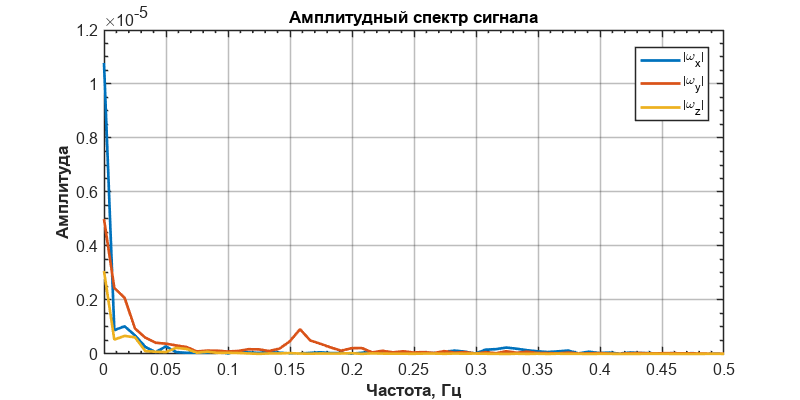

% Преобразование Фурье
Fs = 1/dt;
N = length(data.time);
f = (0:N-1)*(Fs/N);
omega = [data.X, data.Y, data.Z];
fftAll = fft(omega);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2), :);
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 0.5]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
legend({'|\omega_x|', '|\omega_y|', '|\omega_z|'}, 'FontSize', 11, 'Location', 'best');
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');
 saveas(gcf, 'fft_ratesY8.png');        % PNG

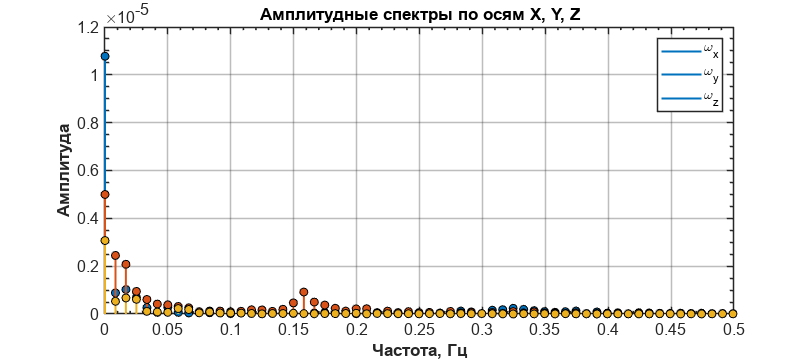

figure('Color','w', 'Position',[100 100 900 400]);
hold on;

% Цвета (по желанию)
colors = lines(3);  % стандартная палитра

% Рисуем вручную каждый спектр как линии вверх + маркеры
for i = 1:3
    for k = 1:length(f_plot)
        plot([f_plot(k) f_plot(k)], [0 amp_plot(k,i)], '-', 'Color', colors(i,:), 'LineWidth', 1.5);  % вертикальная линия
        plot(f_plot(k), amp_plot(k,i), 'o', 'MarkerSize', 6, 'MarkerFaceColor', colors(i,:), 'MarkerEdgeColor', 'k');  % кружок
    end
end

xlim([0 0.5]);
grid on;

xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');
title('Амплитудные спектры по осям X, Y, Z', 'FontSize', 14);

legend({'\omega_x', '', '\omega_y', '', '\omega_z'}, ...
       'FontSize', 11, 'Interpreter', 'tex', 'Location', 'northeast');

set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');

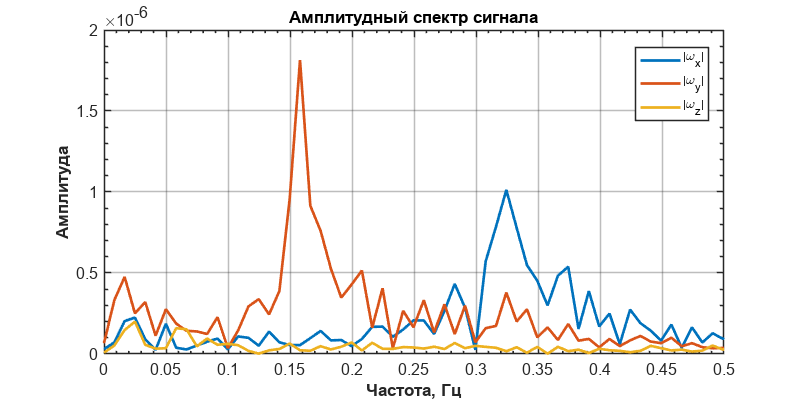

% Преобразование Фурье
Fs = 1/dt;
N = length(data.time);
f = (0:N-1)*(Fs/N);
omega = [dx, dy, dz];
fftAll = fft(omega);
amp = abs(fftAll)/N;


f_plot = f(1:floor(N/2));
amp_plot = amp(1:floor(N/2), :);
figure('Color','w', 'Position',[100 100 800 400]);  % белый фон и размер

plot(f_plot, amp_plot, 'LineWidth', 2);             % более жирная линия
xlim([0 0.5]);                                       % ограничение по частоте

grid on;

% Подписи осей
xlabel('Частота, Гц', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Амплитуда', 'FontSize', 12, 'FontWeight', 'bold');

% Заголовок
title('Амплитудный спектр сигнала', 'FontSize', 14);
legend({'|\omega_x|', '|\omega_y|', '|\omega_z|'}, 'FontSize', 11, 'Location', 'best');
% Стилизация осей
set(gca, ...
    'FontSize', 12, ...
    'LineWidth', 1.2, ...
    'Box', 'on', ...
    'GridAlpha', 0.3, ...
    'XMinorTick', 'on', ...
    'YMinorTick', 'on');
 saveas(gcf, 'fft_ratesY8_acc.png');        % PNG